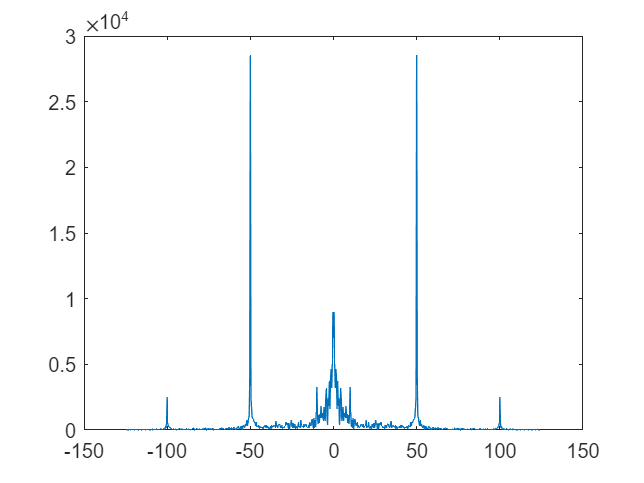

clear;clc;clf;
load("up.mat")
%waveletType = 'db4';   good
waveletType='dmey';
level = 11;  % 分解层数可以根据你的数据调整

data=up(:,:);
num_samples=700;
num_channels=length(data(1,:));
data_filtered = zeros(size(data));  % 初始化过滤后的数据矩阵
temp=zeros(size(data));
fs=250;

%FFT
fftDATA=fftshift(abs(fft(data(:,10))));
fshift=(-num_samples/2:num_samples/2-1) * (fs / num_samples);
figure(1);
plot(fshift,fftDATA);

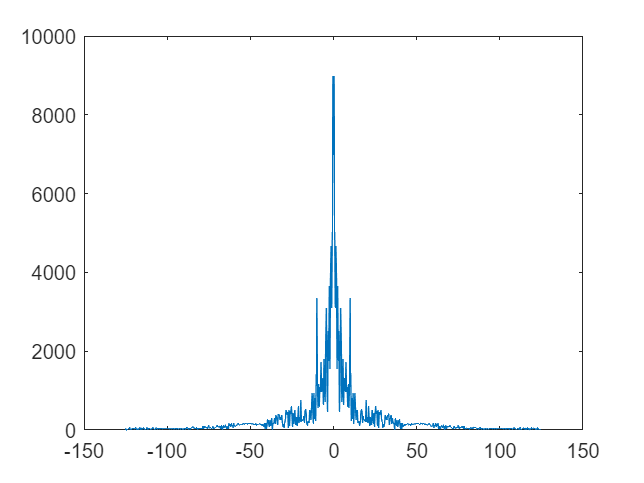


% 设计带阻滤波器
freq_band = [40 60]; % 带阻频率范围
wo = mean(freq_band) / (fs / 2); % 带阻中心频率的归一化
bw = (freq_band(2) - freq_band(1)) / (fs / 2); % 带宽的归一化
[b, a] = iirnotch(wo, bw);

% 对每一列信号进行带阻滤波
for i = 1:num_channels
    temp(:, i) = filtfilt(b, a, data(:, i));
end

freq_band = [90 110]; % 带阻频率范围
wo = mean(freq_band) / (fs / 2); % 带阻中心频率的归一化
bw = (freq_band(2) - freq_band(1)) / (fs / 2); % 带宽的归一化
[b, a] = iirnotch(wo, bw);

% 对每一列信号进行带阻滤波
for i = 1:num_channels
    data_filtered(:, i) = filtfilt(b, a, temp(:, i));
end

fftDATA=fftshift(abs(fft(data_filtered(:,10))));
fshift=(-num_samples/2:num_samples/2-1) * (fs / num_samples);
figure(1);
plot(fshift,fftDATA);

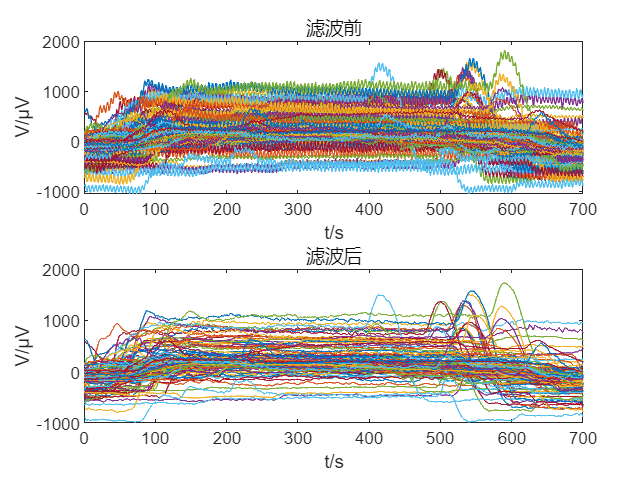

% 滤波前后对比
figure(1);
subplot(2,1,1)
plot(data);
xlabel('t/s');
ylabel('V/μV');
title('滤波前');

subplot(2,1,2)
plot(data_filtered);
xlabel('t/s');
ylabel('V/μV');
title('滤波后');